# Electrode Charge Over Time

select dump file

clear variables;

fileName = "C:\Users\sunsk\MATLAB\LAMMPS\Logs\grouped\argon dist\no counter\dump.allq.none.xyz";

[dumpData] = scan_DumpCustom(fileName);

if ~contains(dumpData{1}.col_names,'q')
    error("Missing charge data in Dumpfile");
elseif ~contains(dumpData{1}.col_names,'x') %asumes x,y,z all come together. 
    error("Missing position data in Dumpfile");
end

Electrode Elements:

top = "Ar";
bot = "Pt";
cat = "Cs";
Bot_List = transpose(find(dumpData{1}.element_list==bot));
Top_List = transpose(find(dumpData{1}.element_list==top));
Cat_List = transpose(find(dumpData{1}.element_list==cat));

Time Units set in LAMMPS

time_units = 1000;

Timestep of Simulation

timestep = 0.5/time_units;



cation_z = NaN(length(dumpData{1}.time),2);
lowerCharge = NaN(length(dumpData{1}.time),1);
upperCharge = NaN(length(dumpData{1}.time),1);
%Calculate charge on electrodes -- element names are hard coded, not generalized
for i = 1:length(dumpData{1}.time)
    chargeTable = parse_DumpCustomOne(fileName, dumpData{1}.time(i), dumpData);
    chargeTable = sortrows(chargeTable,'id');
    lowerCharge(i,:) = sum(chargeTable(Bot_List,:).q);
    upperCharge(i,:) = sum(chargeTable(Top_List,:).q);
    cation_z(i,:) = chargeTable(Cat_List,:).z;
end
%Count electrode atoms
countTop = length(Top_List);
countBot = length(Bot_List);

Plot

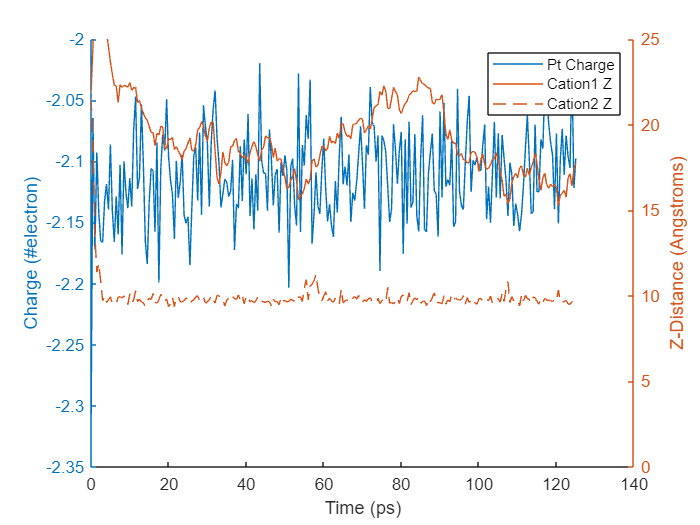

figure
yyaxis left
hold on;
plot(dumpData{1}.time*timestep,lowerCharge);
if countTop
    plot(dumpData{1}.time*timestep,upperCharge);
end
ylabel("Charge (#electron)");
yyaxis right
plot(dumpData{1}.time*timestep,cation_z(:,1));
plot(dumpData{1}.time*timestep,cation_z(:,2));
ylabel("Z-Distance (Angstroms)");
ylim([0 25]);
if countTop
    legend(["Pt Charge" "Ar Charge" "Cation1 Z" "Cation2 Z"]);
else
    legend(["Pt Charge" "Cation1 Z" "Cation2 Z"]);
end
xlabel("Time (ps)");
hold off;



disp(strcat("Ave Pt Electrode Charge: ", string(mean(lowerCharge(5,:)))));

Ave Pt Electrode Charge: -2.1415


if countTop
    disp(strcat("Ave Ar Electrode Charge: ", string(mean(upperCharge(5,:)))));
end
disp(strcat("Num Pt Atoms: ",string(countBot)));

Num Pt Atoms: 144


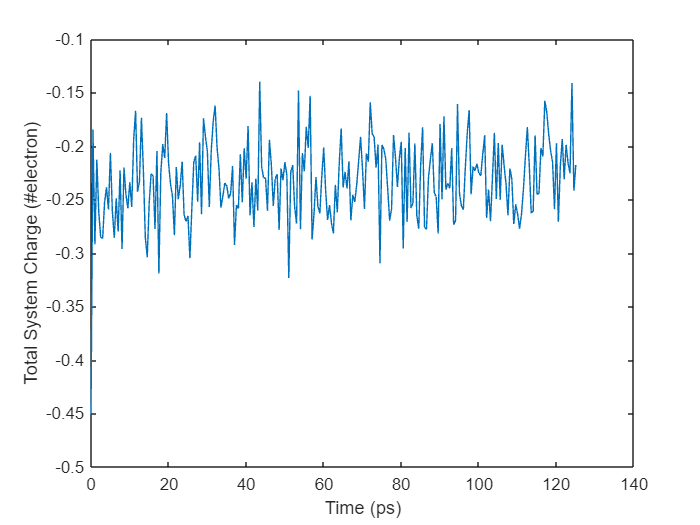

if countTop
    totalCharge = lowerCharge+upperCharge+0.94*2;
else
    totalCharge = lowerCharge+0.94*2;
end
figure;
plot(dumpData{1}.time*timestep,totalCharge);
ylabel("Total System Charge (#electron)");
xlabel("Time (ps)");